clc
clear
echo on
echo off 
disp('Simulating  ...')

Simulating  ...



gray=[0.75 0.75 0.75];

load data.mat;

干扰形式

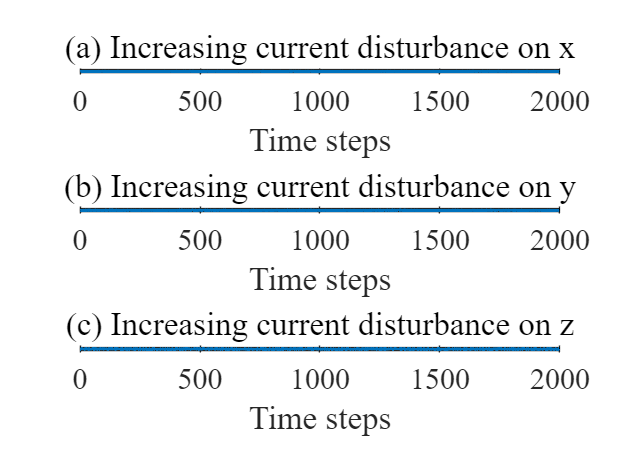

figure(1);
subplot(3,1,1);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Wave_state(1,:),'-',LineWidth=2);
ylabel('Current Speed');
xlabel('Time steps');
title('(a) Increasing current disturbance on x');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(3,1,2);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Wave_state(2,:),'-',LineWidth=2);
ylabel('Current Speed');
xlabel('Time steps');
title('(b) Increasing current disturbance on y');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(3,1,3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Wave_state(3,:),'-',LineWidth=2);
ylabel('Current Speed');
xlabel('Time steps');
title('(c) Increasing current disturbance on z');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

%偏差分析

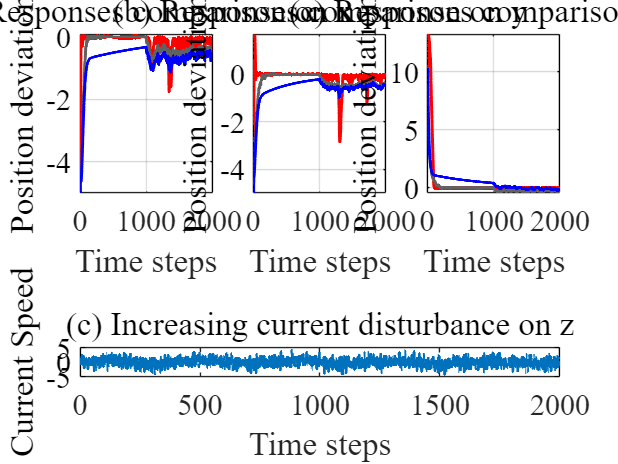

xout_SMC = xout_SMC';
xout_COC = xout_COC';
xout_lqr = xout_lqr';

figure(1)
subplot(2,3,1);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(1,:),'-',Color='Red',LineWidth=2);
hold on;
plot(Error_COC_state(1,:),'-',Color=gray,LineWidth=2);
hold on;
plot(Error_lqr_state(1,:),'-',Color='Blue',LineWidth=2);
grid on;
ylabel('Position deviation');
xlabel('Time steps');
title('(a) Responses comparison on x');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(2,3,2);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(2,:),'-',Color='Red',LineWidth=2);
hold on;
plot(Error_COC_state(2,:),'-',Color=gray,LineWidth=2);
hold on;
plot(Error_lqr_state(2,:),'-',Color='Blue',LineWidth=2);
grid on;
ylabel('Position deviation');
xlabel('Time steps');
title('(b) Responses comparison on y');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(2,3,3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(3,:),'-',Color='Red',LineWidth=2);
hold on;
plot(Error_COC_state(3,:),'-',Color=gray,LineWidth=2);
hold on;
plot(Error_lqr_state(3,:),'-',Color='Blue',LineWidth=2);
grid on;
ylabel('Position deviation');
xlabel('Time steps');
title('(c) Responses comparison on z');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

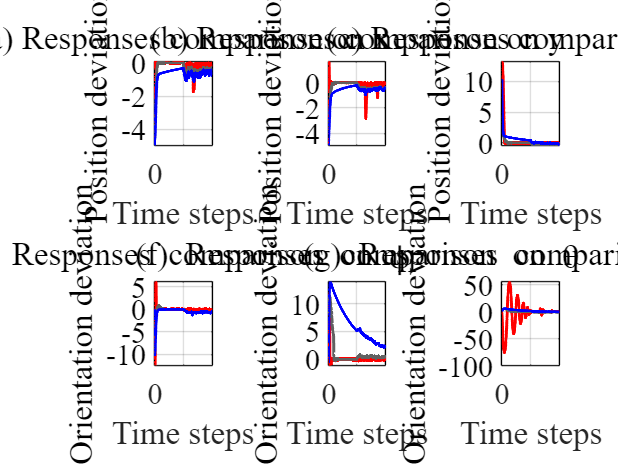


subplot(2,3,4);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(4,:),'-',Color='Red',LineWidth=2);
hold on;
plot(Error_COC_state(4,:),'-',Color=gray,LineWidth=2);
hold on;
plot(Error_lqr_state(4,:),'-',Color='Blue',LineWidth=2);
grid on;
ylabel('Orientation deviation');
xlabel('Time steps');
title('(d) Responses comparison on \phi');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(2,3,5);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(5,:),'-',Color='Red',LineWidth=2);
hold on;
plot(Error_COC_state(5,:),'-',Color=gray,LineWidth=2);
hold on;
plot(Error_lqr_state(5,:),'-',Color='Blue',LineWidth=2);
grid on;
ylabel('Orientation deviation');
xlabel('Time steps');
title('(f) Responses comparison on \theta');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

subplot(2,3,6);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');
plot(Error_SMC_state(6,:),'-',Color='Red',LineWidth=2);
hold on;
plot(Error_COC_state(6,:),'-',Color=gray,LineWidth=2);
hold on;
plot(Error_lqr_state(6,:),'-',Color='Blue',LineWidth=2);
grid on;
ylabel('Orientation deviation');
xlabel('Time steps');
title('(g) Responses comparison on \psi');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

偏差分离

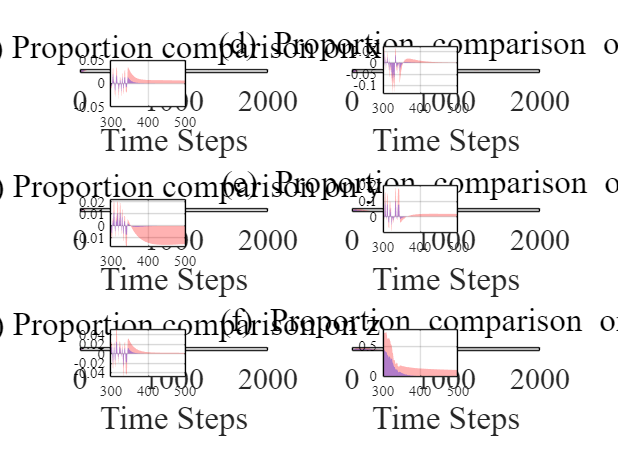

Time_bias_extraction = 1:1999;
Bound_bias_extraction = zeros(1,1999);
figure(5);
subplot(3,2,1);
% yyaxis right;
% plot(K_co_state_smooth(1,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(1,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(1,:),Bound_bias_extraction],'b');
grid on;
ylabel('Position deviation');
xlabel('Time Steps');
title('(a) Proportion comparison on x');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h1 = axes('Position',[0.18 0.77 0.12 0.1]);
axes(h1);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(1,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(1,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

% h2 = axes('Position',[0.32 0.77 0.12 0.1]);
% axes(h2);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(1,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(1,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h2,'xlim',[600 800]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

subplot(3,2,3);
% yyaxis right;
% plot(K_co_state_smooth(2,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(2,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(2,:),Bound_bias_extraction],'b');
grid on;
ylabel('Position deviation');
xlabel('Time Steps');
title('(b) Proportion comparison on y');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h3 = axes('Position',[0.18 0.47 0.12 0.1]);
axes(h3);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(2,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(2,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h3,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

% h4 = axes('Position',[0.32 0.46 0.12 0.1]);
% axes(h4);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(2,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(2,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h4,'xlim',[600 800]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

subplot(3,2,5);
% yyaxis right;
% plot(K_co_state_smooth(3,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(3,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(3,:),Bound_bias_extraction],'b');
grid on;
ylabel('Position deviation');
xlabel('Time Steps');
title('(c) Proportion comparison on z');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h5 = axes('Position',[0.18 0.19 0.12 0.1]);
axes(h5);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(3,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(3,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h5,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

% h6 = axes('Position',[0.33 0.19 0.12 0.1]);
% axes(h6);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(3,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(3,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h6,'xlim',[900 1100]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

subplot(3,2,2);
% yyaxis right;
% plot(K_co_state_smooth(4,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(4,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(4,:),Bound_bias_extraction],'b');
grid on;
ylabel('Orientation deviation');
xlabel('Time Steps');
title('(d) Proportion comparison on \phi');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h7 = axes('Position',[0.62 0.8 0.12 0.1]);
axes(h7);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(4,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(4,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h7,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

% h8 = axes('Position',[0.77 0.8 0.12 0.1]);
% axes(h8);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(4,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(4,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h8,'xlim',[1200 1400]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

subplot(3,2,4);
% yyaxis right;
% plot(K_co_state_smooth(5,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(5,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(5,:),Bound_bias_extraction],'b');
grid on;
ylabel('Orientation deviation');
xlabel('Time Steps');
title('(e) Proportion comparison on \theta');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h9 = axes('Position',[0.62 0.50 0.12 0.1]);
axes(h9);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(5,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(5,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h9,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;

% h10 = axes('Position',[0.77 0.50 0.12 0.1]);
% axes(h10);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(5,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(5,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h10,'xlim',[1200 1400]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

subplot(3,2,6);
% yyaxis right;
% plot(K_co_state_smooth(6,:),'--',Color=gray,LineWidth=1.5)
% hold on;
% yyaxis left;
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(6,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(6,:),Bound_bias_extraction],'b');
grid on;
ylabel('Orientation deviation');
xlabel('Time Steps');
title('(f) Proportion comparison on \psi');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');

h11 = axes('Position',[0.62 0.19 0.12 0.1]);
axes(h11);
f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(6,:),Bound_bias_extraction],'r');
hold on;
f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(6,:),Bound_bias_extraction],'b');
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h11,'xlim',[300 500]);
set(gca,'FontName','Times New Roman');
set(f1,'edgealpha',0,'facealpha',0.3);
set(f2,'edgealpha',0,'facealpha',0.3);
grid on;


% h12 = axes('Position',[0.77 0.19 0.12 0.1]);
% axes(h12);
% f1 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_state(6,:),Bound_bias_extraction],'r');
% hold on;
% f2 = fill([Time_bias_extraction,fliplr(Time_bias_extraction)],[Error_COC_xr_state(6,:),Bound_bias_extraction],'b');
% set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
% set(h12,'xlim',[1200 1400]);
% set(gca,'FontName','Times New Roman');
% set(f1,'edgealpha',0,'facealpha',0.3);
% set(f2,'edgealpha',0,'facealpha',0.3);
% grid on;

%推力分配

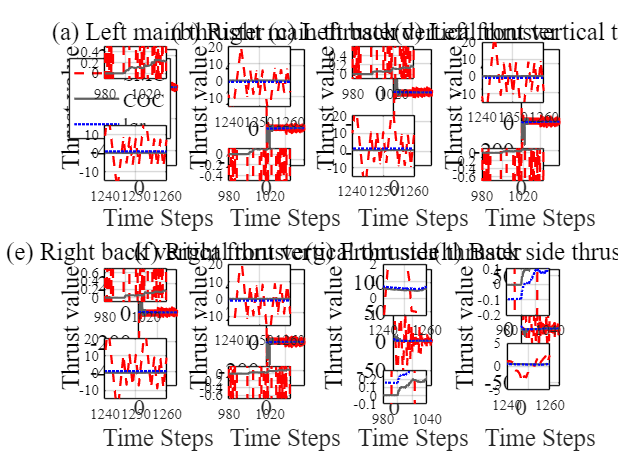

figure(4);
subplot(2,4,1);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(a) Left main thruster');
legend('SMC','COC','lqr');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h1 = axes('Position',[0.17 0.61 0.1 0.12]);
axes(h1);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h1,'xlim',[1240 1260],'ylim',[-15 15]);
set(gca,'FontName','Times New Roman');
grid on;

h9 = axes('Position',[0.17 0.83 0.1 0.07]);
axes(h9);
plot(F_SMC_state(1,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(1,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(1,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h9,'xlim',[980 1040],'ylim',[-0.1 0.5]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,2);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(b) Right main thruster');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h2 = axes('Position',[0.37 0.77 0.1 0.13]);
axes(h2);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h2,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h10 = axes('Position',[0.37 0.61 0.1 0.07]);
axes(h10);
plot(F_SMC_state(2,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(2,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(2,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h10,'xlim',[980 1040],'ylim',[-0.5 0.1]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,3);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(c) Left back vertical thruster');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h3 = axes('Position',[0.57 0.62 0.1 0.13]);
axes(h3);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h3,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h11 = axes('Position',[0.57 0.83 0.1 0.07]);
axes(h11);
plot(F_SMC_state(3,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(3,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(3,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h11,'xlim',[980 1040],'ylim',[-0.1 0.6]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,4);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(d) Left front vertical thruster');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h4 = axes('Position',[0.78 0.78 0.1 0.13]);
axes(h4);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h4,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h12 = axes('Position',[0.78 0.61 0.1 0.07]);
axes(h12);
plot(F_SMC_state(4,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(4,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(4,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h12,'xlim',[980 1040],'ylim',[-0.7 0.1]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,5);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(e) Right back vertical thruster');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h5 = axes('Position',[0.17 0.14 0.1 0.13]);
axes(h5);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h5,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h13 = axes('Position',[0.17 0.35 0.1 0.07]);
axes(h13);
plot(F_SMC_state(5,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(5,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(5,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h13,'xlim',[980 1040],'ylim',[-0.1 0.7]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,6);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(f) Right front vertical thruster');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h6 = axes('Position',[0.37 0.3 0.1 0.13]);
axes(h6);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h6,'xlim',[1240 1260],'ylim',[-15 20]);
set(gca,'FontName','Times New Roman');
grid on;

h14 = axes('Position',[0.37 0.14 0.1 0.07]);
axes(h14);
plot(F_SMC_state(6,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(6,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(6,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h14,'xlim',[980 1040],'ylim',[-0.7 0.2]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,7);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(g) Front side thruster');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h7 = axes('Position',[0.62 0.32 0.07 0.11]);
axes(h7);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h7,'xlim',[1240 1260],'ylim',[-1 2]);
set(gca,'FontName','Times New Roman');
grid on;

h15 = axes('Position',[0.62 0.13 0.07 0.07]);
axes(h15);
plot(F_SMC_state(7,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(7,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(7,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h15,'xlim',[980 1040],'ylim',[-0.1 0.3]);
set(gca,'FontName','Times New Roman');
grid on;

subplot(2,4,8);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
grid on;
ylabel('Thrust value');
xlabel('Time Steps');
title('(h) Back side thruster');
set(gca,'FontSize',15,'FontName','Times New Roman','ycolor','Black');

h8 = axes('Position',[0.82 0.16 0.07 0.1]);
axes(h8);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h8,'xlim',[1240 1260],'ylim',[-5 5]);
set(gca,'FontName','Times New Roman');
grid on;

h16 = axes('Position',[0.82 0.32 0.07 0.1]);
axes(h16);
plot(F_SMC_state(8,:),'--',Color='Red',LineWidth=1.5);
hold on;
plot(F_COC_state(8,:),'-',Color=gray,LineWidth=1.5);
hold on;
plot(F_lqr_state(8,:),':',Color='Blue',LineWidth=1.5);
set(gca,'FontSize',10,'FontName','Times New Roman','ycolor','Black');
set(h16,'xlim',[980 1040],'ylim',[-0.2 0.1]);
set(gca,'FontName','Times New Roman');
grid on;

损失函数比较

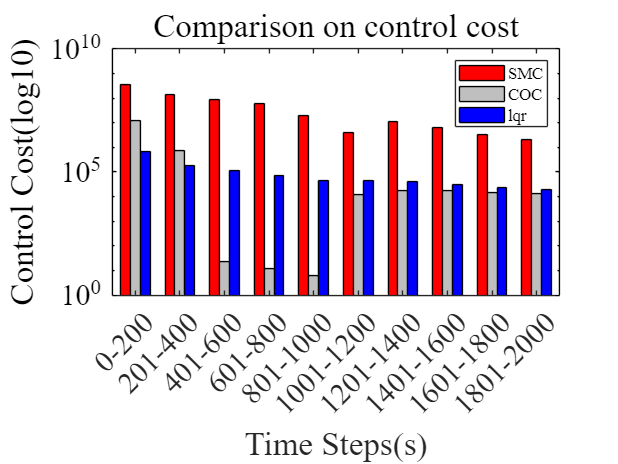

J_COC_terms = ones(1,10);
J_SMC_terms = ones(1,10);
J_lqr_terms = ones(1,10);

for i = 1:10
    J_COC_terms(i) = sum(J_COC_State(200*(i-1)+1:200*i-1));
    J_lqr_terms(i) = sum(J_LQR_State(200*(i-1)+1:200*i-1));
    J_SMC_terms(i) = sum(J_SMC_State(200*(i-1)+1:200*i-1));
end

figure;%确定图片的位置和大小，[x y width height]
%准备数据
Y=[J_SMC_terms',J_COC_terms',J_lqr_terms'];
% Y=[70,75,80,85;70,75,80,85;70,75,80,85;70,75,80,85];
X=1:10;
 %画出4组柱状图，宽度1
h=bar(X,Y,1);      
 %修改横坐标名称、字体
set(gca,'XTickLabel',{'0-200','201-400','401-600','601-800','801-1000','1001-1200','1201-1400','1401-1600','1601-1800','1801-2000'},'FontSize',10,'FontName','Times New Roman');
set(gca,'YScale','log','FontSize',10,'FontName','Times New Roman');
% 设置柱子颜色,颜色为RGB三原色，每个值在0~1之间即可
set(h(1),'FaceColor',[255,0,0]/255)     
set(h(2),'FaceColor',[191,191,191]/255)    
set(h(3),'FaceColor',[0,0,255]/255)      
% ylim([60,100]);      %y轴刻度
%修改x,y轴标签
ylabel('Control Cost(log10)');
xlabel('Time Steps(s)'); 
%修改图例
legend({'SMC','COC','lqr'},'FontSize',11);
title('Comparison on control cost');
set(gca,'FontSize',20,'FontName','Times New Roman','ycolor','Black');